# Eksamensæt

**M3DYN1-03 Dynamik -- 09-06-2023**

**Eksamensnummer -- 185432**

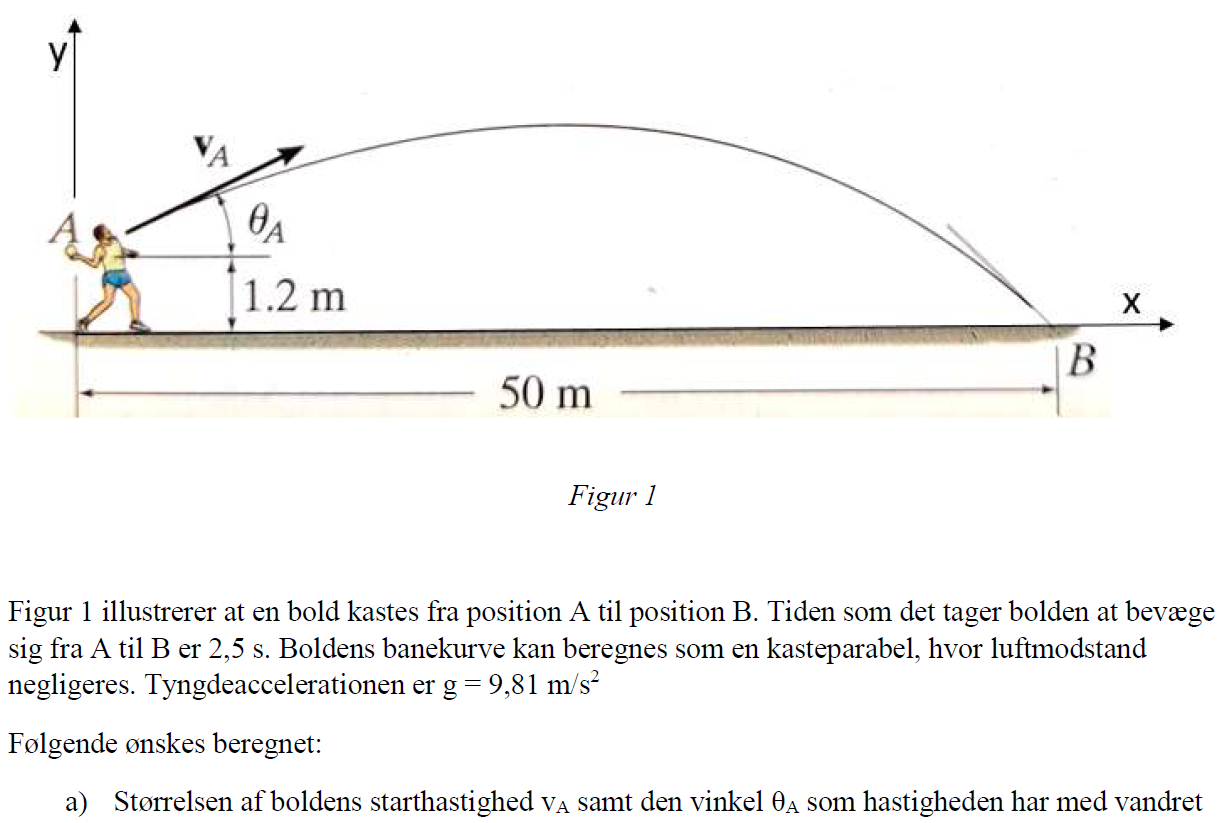

**Vi pladsere vores koordinat system med origo i kasteresn venstre fod**

Vi op stiller to ligninger med to ubekendte.

ligning i x-retningen er


$$x = x_0 + v_{x0} \cdot t$$


ligning i y-retning


$$y = y_0 + v_{y0} \cdot t - \frac{g \cdot t^2}{2}$$


clear all
clf
format shortg

t_f = 2.5;
g = 9.81;
s = 50;
s_0 = 0;
t = t_f;
syms v_0 theta
v_x0 = v_0 * cos(theta)

$$v\_x0 = v_{0}\,\cos\left(\theta \right)$$

v_y0 = v_0 * sin(theta)

$$v\_y0 = v_{0}\,\sin\left(\theta \right)$$

x = 50;
x_0 = 0;
y = 0;
y_0 = 1.2;

eq_sx = x == x_0 + v_x0*t

$$eq\_sx = 50=\frac{5\,v_{0}\,\cos\left(\theta \right)}{2}$$

eq_sy = y == y_0 + v_y0*t - g*t^2 / 2

$$eq\_sy = 0=\frac{5\,v_{0}\,\sin\left(\theta \right)}{2}-\frac{4713}{160}$$


[v_0_sol, theta_sol] = solve([eq_sx, eq_sy], [v_0, theta]);
v_0 = v_0_sol(1);
v_0_ = vpa(v_0_sol(1),5)

$$v\_0\_ = 23.213$$

theta_rad = theta_sol(1);
theta_rad_ = vpa(theta_sol(1),5)

$$theta\_rad\_ = 0.53238$$

theta_deg = vpa(rad2deg(theta_rad), 3)

$$theta\_deg = 30.5$$

Således er start hastigheden

$v_0 = 23,2$ m/s^2

og vinklen


$$\theta = 30,5\degree$$


Dette findes ved at op stille hastigheds ligninger for x og y retningen

De to komposanter samles med pythagoras.

v_x = v_0 * cos(theta_rad);
vpa(v_x, 5)

$$ans = 20.0$$

v_y = v_0 * sin(theta_rad) - g * t;
vpa(v_y, 5)

$$ans = -12.742$$

v = sqrt(v_x^2 + v_y^2);
vpa(v, 5)

$$ans = 23.714$$

Vi får nu at hastigheden i x-reningen ikke ændres pga konstant hastighed, men i y-reningen har vi tyngde accelerationen som ændre hastigheden. I B får vi dermed resultaterne 


$$v_xB = 20\ \text{m/s}^2 \\
v_yB = -12,7\ \text{m/s}^2 \\
v = 23,7\ \text{m/s}^2$$


Det ses at start hastigheden er en lille smule lavere end slut hastigheden. Dette giver god mening da vi slutter i et tyngdefelt der er længere nede end i A.

top punktets tid findes når y-hastigheden er v_y0 = 0.

derefter kan denne tid indsættes i ligningerne for x og y pladsering.

syms t
eq_ytop = 0 == v_0 * sin(theta_rad) - g * t;

t_top = vpa(solve(eq_ytop, t),5)

$$t\_top = 1.201070336391437308868501529052$$

x_top = x_0 + (v_0 * cos(theta_rad))*t_top;
vpa(x_top, 5)

$$ans = 24.021$$

y_top = y_0 + (v_0 * sin(theta_rad))*t_top - g*t_top^2 / 2;
vpa(y_top, 5)

$$ans = 8.2758$$

Vi får således koordinatsætet


$$(24,02; 8,28) \\
x = 24,02\ \text{m} \\
y = 8,28\ \text{m}$$


Hvilket passer godt med at vi når top punktet lidt før midten af den fulde kaste længde.

først isoleres t i x-pladserings ligningen og derefter substitueres den ind i y-pladserings ligningen.

Den kan nu plottes som $y(x)$

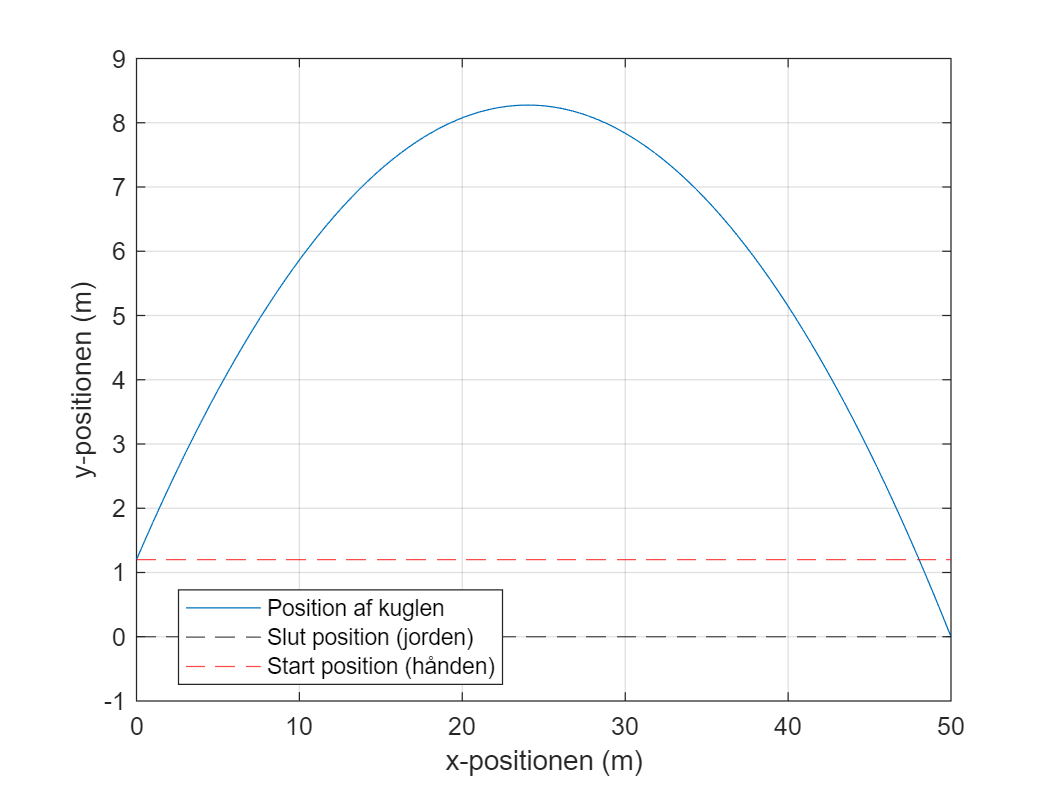

syms x t y
t_insert = x == x_0 + (v_0 * cos(theta_rad))*t;

x_eq = solve(t_insert, t);
y(x) = y_0 + (v_0 * sin(theta_rad))*x_eq - g*x_eq^2 / 2;
x_lin = linspace(0,50,100);
figure(1)
plot(x_lin, y(x_lin), DisplayName='Position af kuglen')
yline(0,'k--', DisplayName='Slut position (jorden)')
yline(1.2,'r--', DisplayName='Start position (hånden)')
xlabel('x-positionen (m)')
ylabel('y-positionen (m)')
grid('on')
legend('Location','best')

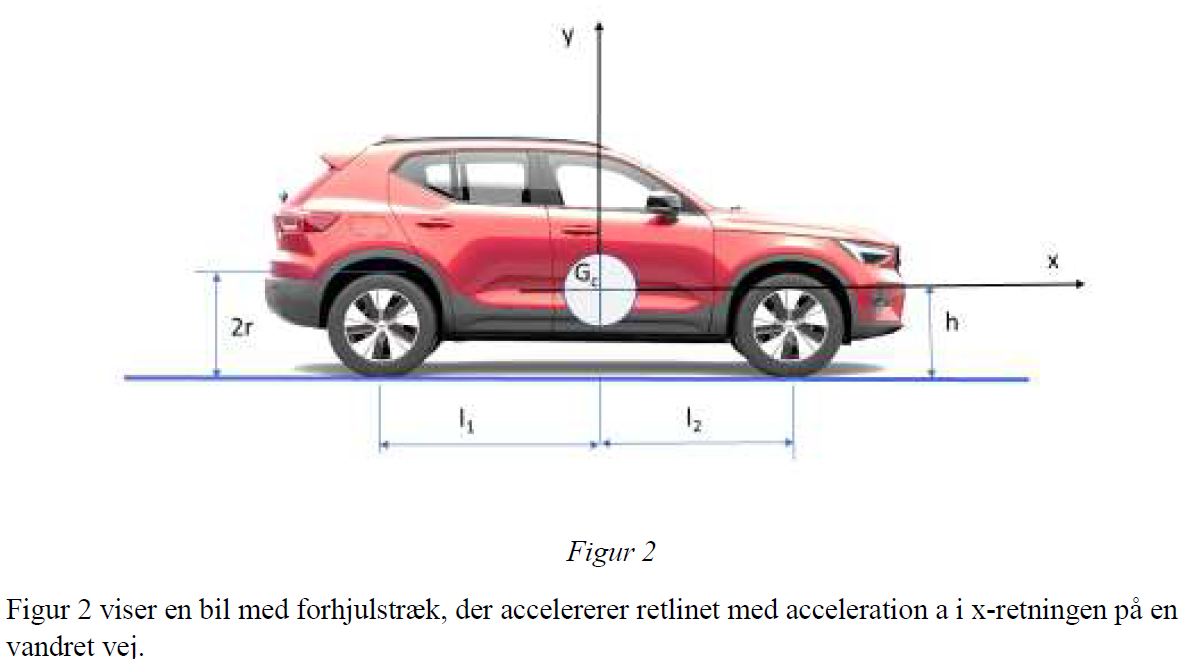

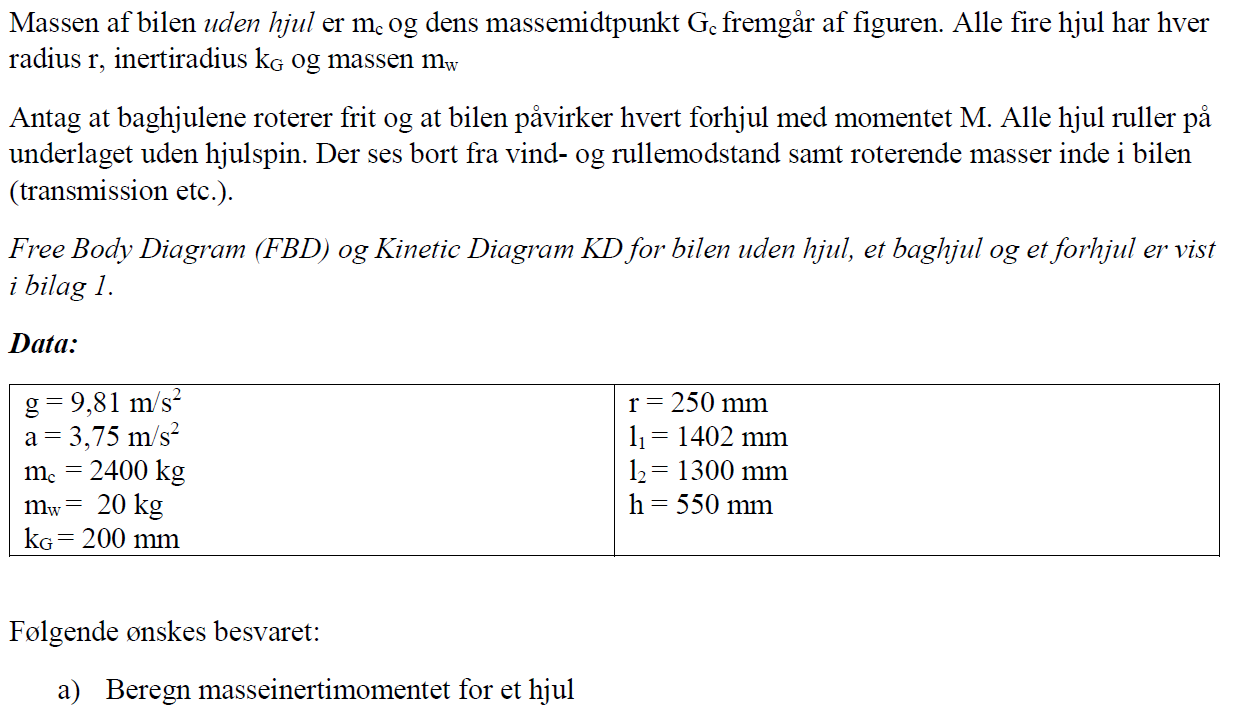

clear all
clf
format shortg
g = 9.81;
a = 3.75;
m_c = 2400;
m_W = 20;
k_G = 0.200;
r = 0.25;
l_1 = 1.402;
l_2 = 1.300;
h = 0.550;

Inertimomentet for et hjul beregnes

I_W = k_G^2 * m_W

I_W =           0.8



$$I_W = 0.8\ \text{kg m}^2$$


vi ved at


$$M = I_W \cdot \alpha = F_W \cdot r$$


med KD digrammet i bilaget har vi

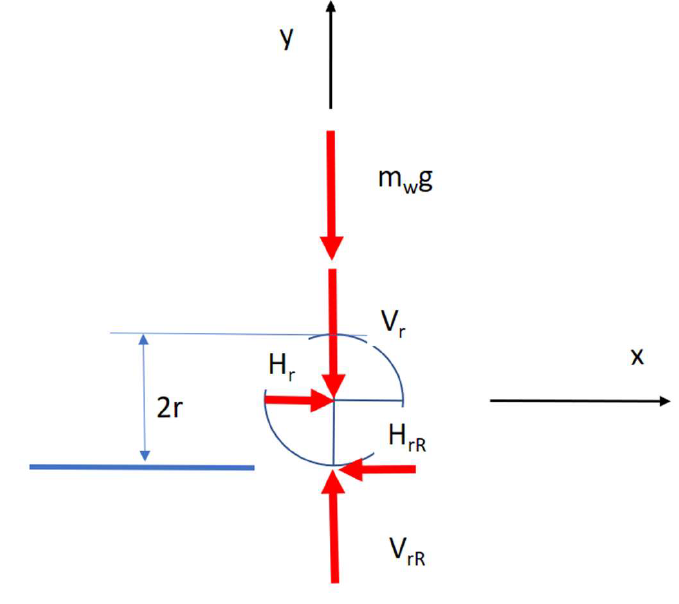

syms alpha H_rR H_fR M
eq_Mr = I_W * alpha == -H_rR * r

$$eq\_Mr = \frac{4\,\alpha }{5}=-\frac{H_{\mathrm{rR}}}{4}$$

eq_Mf = I_W * alpha == H_fR * r - M

$$eq\_Mf = \frac{4\,\alpha }{5}=\frac{H_{\mathrm{fR}}}{4}-M$$

Jeg mangler her en sidste ligning til at løse for alpha

Ville ellers ha stillede lige mange ligninger og ubkendte op og løse for $\alpha$

[alpha_sol, M_sol] = solve([eq_Mr, eq_Mf], [alpha, M])

$$alpha\_sol = -\frac{5\,H_{\mathrm{rR}}}{16}$$

$$M\_sol = \frac{H_{\mathrm{fR}}}{4}+\frac{H_{\mathrm{rR}}}{4}$$

alpha = -15

alpha =    -15


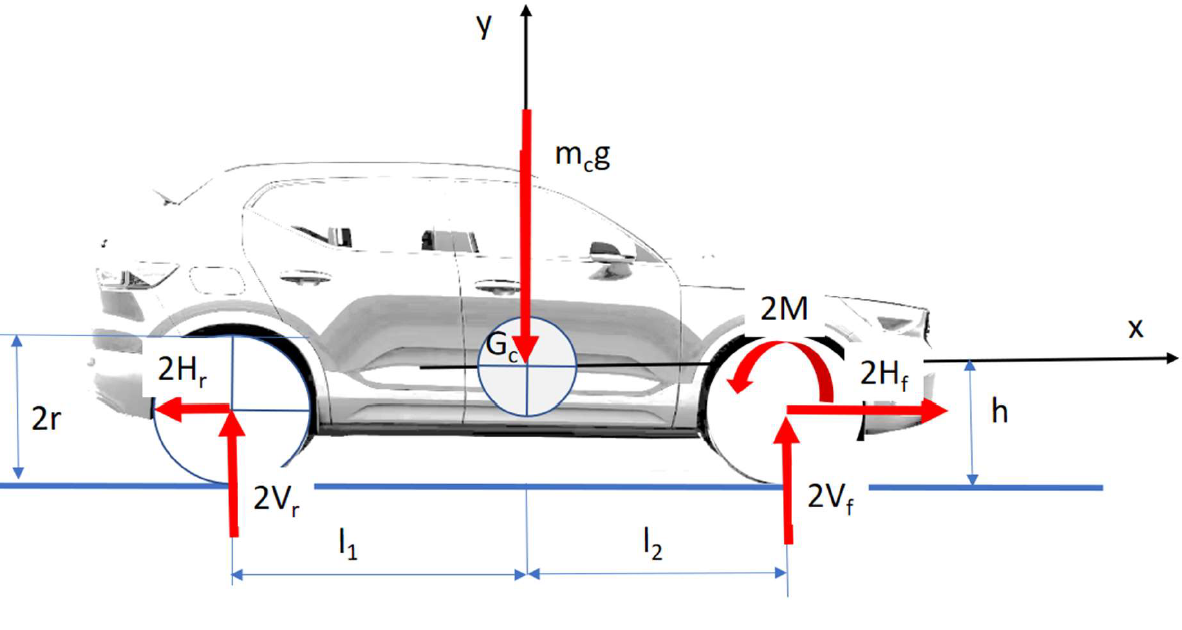

Vi opstiller de tre bevægellses ligninger i y og x retningen og moment ligningen.


$$\sum F_y = - m_c \cdot g + 2V_r + 2V_f = 0 \\
\sum F_x = 2H_r + 2H_f = m_c \cdot a \\
\sum M = - 2V_r \cdot l_1 + 2V_f \cdot l_2  - 2H_r \cdot (2r - h) + 2H_f \cdot (2r - h) + 2M= I_c \cdot \alpha_G = 0 $$


I momentligningen ses H_r og H_f som den kraft hjulene skubber med, og at denne kraft oprindeligt kommer fra underlaget.

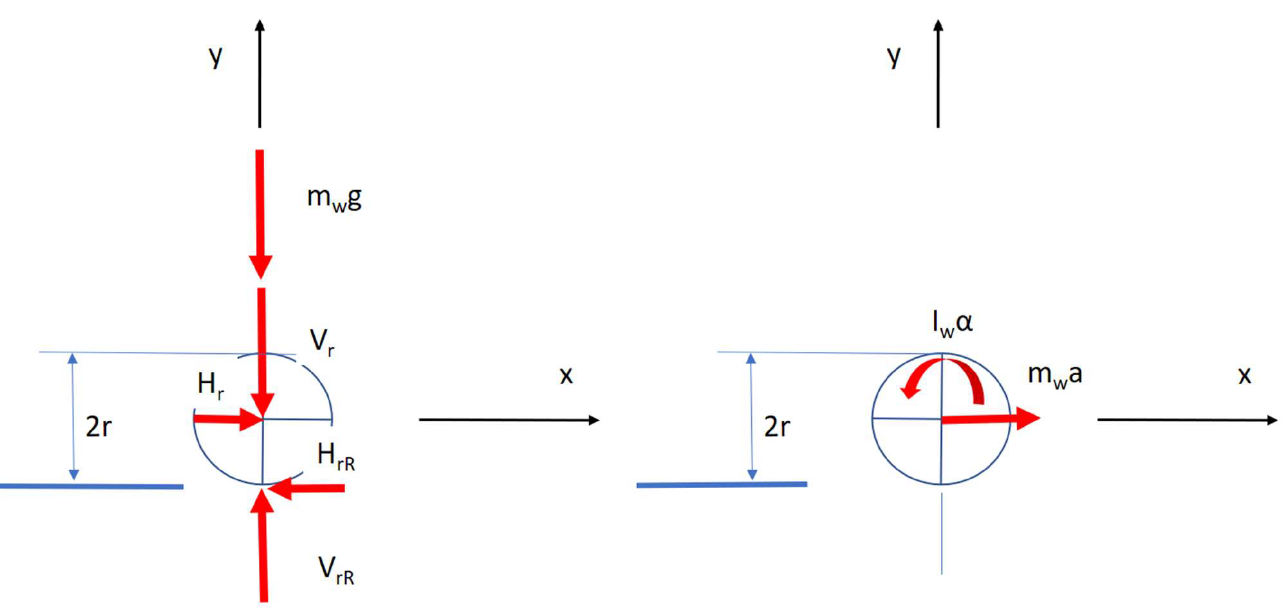


$$\sum F_y = - m_W \cdot g - V_r + V_{rR} = 0 \\
\sum F_x = H_r - H_{rR} = m_W \cdot a \\
\sum M = -H_{rR} \cdot r = I_W \cdot \alpha$$


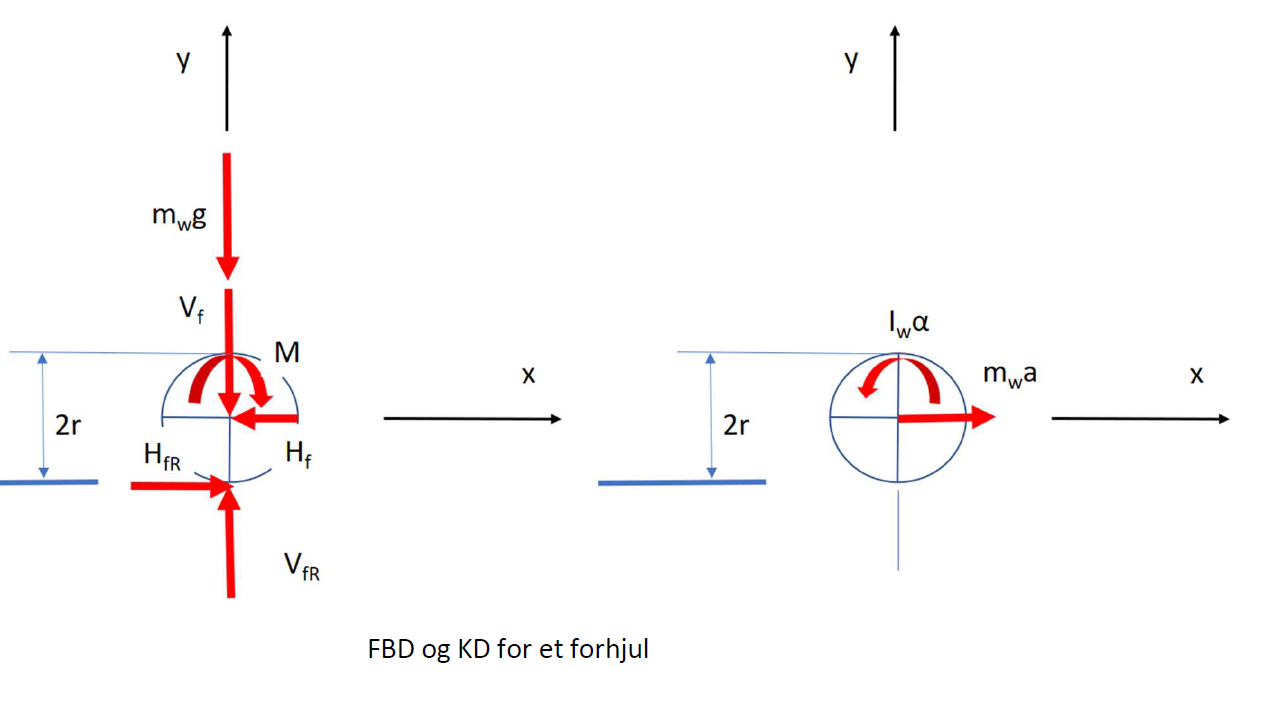


$$\sum F_y = - m_W \cdot g - V_f + V_{fR} = 0 \\
\sum F_x = - H_f + H_{fR} = m_W \cdot a \\
\sum M = H_{fR} \cdot r + M = I_W \cdot \alpha$$


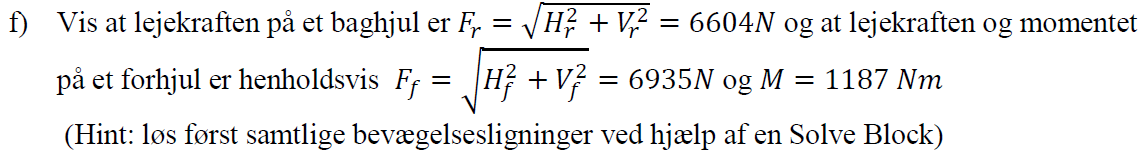

Nåede ikke denne opgave men ville stille alle ligningerne op og solve

syms  V_r V_f H_r H_f M H_rR H_fR V_rR V_fR
eq_bil_Fy = -m_c * g + 2*V_r + V_f == 0;
eq_bil_F_x = 2 * H_r + 2*H_f == m_c * a;
eq_bil_M = -2 * V_r * l_1 + 2*V_f * l_2 - 2* H_r * (2*r - h) + 2 * H_f * (2*r - h) + 2 * M == 0;

F_ry = -m_W * g - V_r + V_rR == 0;
F_rx = H_r - H_rR == m_W * a;
M_r = -H_rR * r == I_W * alpha;

F_fy = -m_W * g - V_f + V_fR == 0;
F_fx = H_f - H_fR == m_W * a;
M_f = -H_fR * r + M == I_W * alpha;

[V_r, V_f, H_r, H_f, M, H_rR, H_fR, V_rR, H_fR] = solve( ...
    [eq_bil_Fy, eq_bil_F_x, eq_bil_M, F_ry, F_rx, M_r, F_fy, F_fx, M_f], ...
    [V_r, V_f, H_r, H_f, M, H_rR, H_fR, V_rR, H_fR])

Error using sym.getEqnsVars>checkVariables
Second argument must be a vector of symbolic variables.

Error in sym.getEqnsVars (line 62)
    checkVariables(vars);

Error in sym/solve>getEqns (line 429)
[eqns, vars] = sym.getEqnsVars

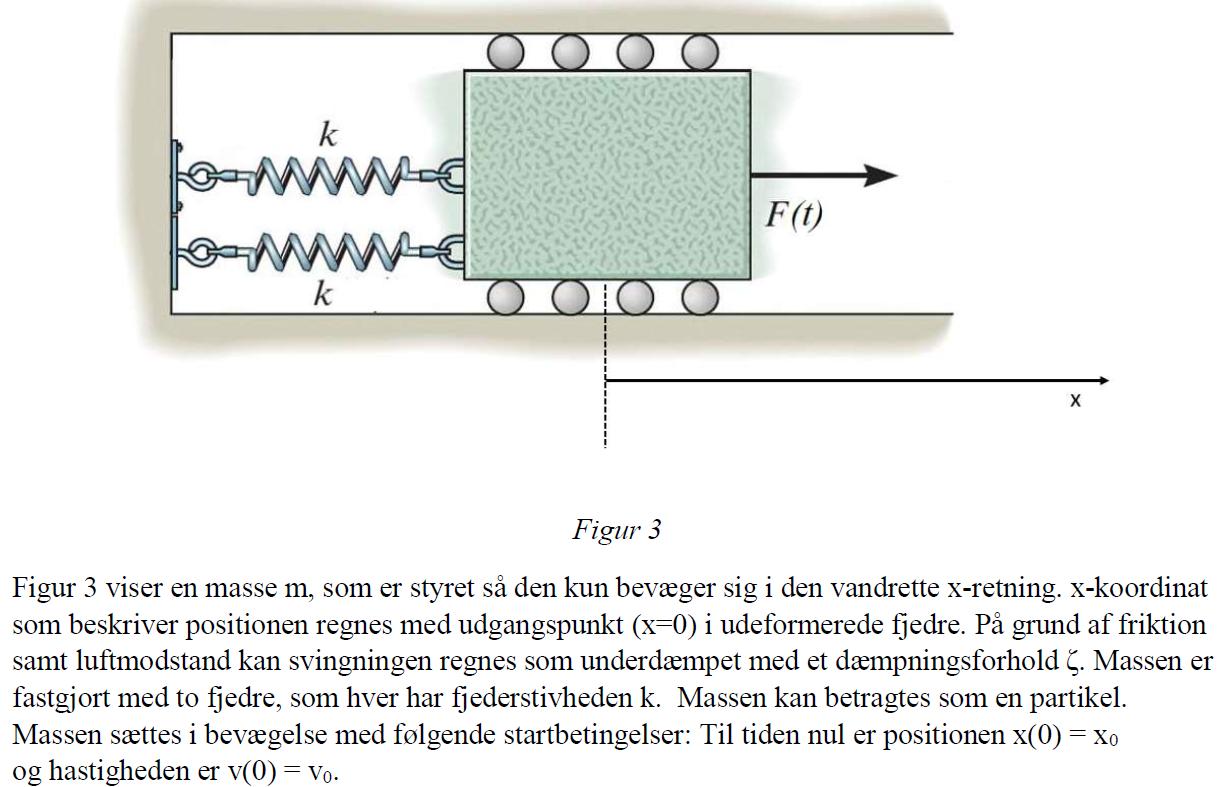

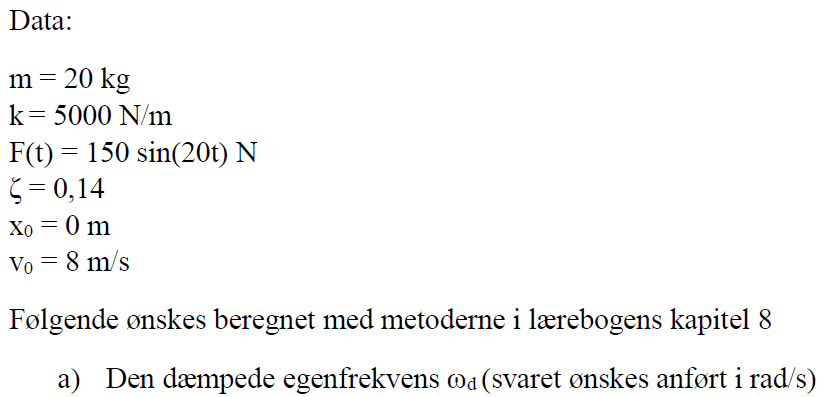

clear all
clf
format shortg

m = 20;
k = 5000 * 2;
syms t A_1 A_2
F(t) = 150 * sin(20*t) %N

$$F(t) = 150\,\sin\left(20\,t\right)$$

omega = 20;
zeta = 0.14;
x_0 =0;
v_0 = 8;
t_0 = 0;

Vi finder egenfrekvensen($\omega_n$)

omega_n = sqrt(k/m)

omega_n =        22.361



$$\omega_n = 22,36\ \text{rad/s}$$


Denne finder vi med ligning 8/20

X_steady(t) = (F(t) / k) / sqrt( (1 - (omega/omega_n)^2)^2 + (1 - (2 * zeta * omega/omega_n)^2) );
vpa(X_steady(t),5)

$$ans = 0.015173\,\sin\left(20.0\,t\right)$$

Således bliver  stedy state amplituden $X = 0,0152\sin(20 \cdot t)$ m.

Hvor den maximale amplitude vil være 0,0152 m 

Først finde den naturlige dæmpede svigningsfrekvens $\omega_d$

syms psi C_s f(t) t f_1(t)

w_d =         22.14



w_d = omega_n*sqrt(1-zeta^2) 

Ligning (8/12) opstilles og benyttes til at finde forskydningen for den komplimentære løsning

x_c(t) = C_s * exp(-zeta * omega_n * t) * (sin(w_d * t + psi)) % Sted funktionen for underdæmpede svininger ligning (8/12) %

$$x\_c(t) = C_{s}\,{\mathrm{e}}^{-\frac{7\,\sqrt{5}\,t}{5}}\,\sin\left(\psi +\frac{\sqrt{5}\,\sqrt{2451}\,t}{5}\right)$$

Ved at differentier forskydningsligningen får vi hastighedes ligningen

x_c1(t) = diff(x_c(t), t) %% Hastigheds funktionen

$$x\_c1(t) = \frac{\sqrt{5}\,\sqrt{2451}\,C_{s}\,{\mathrm{e}}^{-\frac{7\,\sqrt{5}\,t}{5}}\,\cos\left(\psi +\frac{\sqrt{5}\,\sqrt{2451}\,t}{5}\right)}{5}-\frac{7\,\sqrt{5}\,C_{s}\,{\mathrm{e}}^{-\frac{7\,\sqrt{5}\,t}{5}}\,\sin\left(\psi +\frac{\sqrt{5}\,\sqrt{2451}\,t}{5}\right)}{5}$$

Vi løser ligningssystemet for C_s og psi

sol = [x_c(t_0) == x_0, x_c1(t_0) == v_0]; %% sættes op i et array så der kan solves for de 2 ukendte. 

S = solve(sol, psi, C_s); %Solver for psi og C_s i vores x lignings system

%udpakker og vudere værdierne fra struct
psi = vpa(S.psi)

$$psi = 0.0$$

C_s = vpa(S.C_s)

$$C\_s = 0.36132942798553755930669118831229$$

x_c(t) = C_s*exp(-zeta * omega_n * t) * (sin(w_d * t + psi));

Dette er den komplimentære forskydningsligning.

Vi finder nu den partikulære løsning

Først redefineres aplituden X

X(t) = (F(t) / k) / sqrt( (1 - (omega/omega_n)^2)^2 + (1 - (2 * zeta * omega/omega_n)^2) )

$$X(t) = \frac{\sqrt{5}\,\sqrt{3054}\,\sin\left(20\,t\right)}{8144}$$

Vi finder start vinklen $\phi$

phi = atan( (2*zeta * omega/omega_n) / (1-(omega/omega_n)^2) )

phi =       0.89691


Vi kan nu opskrive den partikulære løsning.

x_p(t) = X * sin(omega * t - phi);

Den samlede ligning er nu den partikulære del + den komplimentære del.

x(t) = x_c(t) + x_p(t);

Der plottes en kurve over bevægelsen

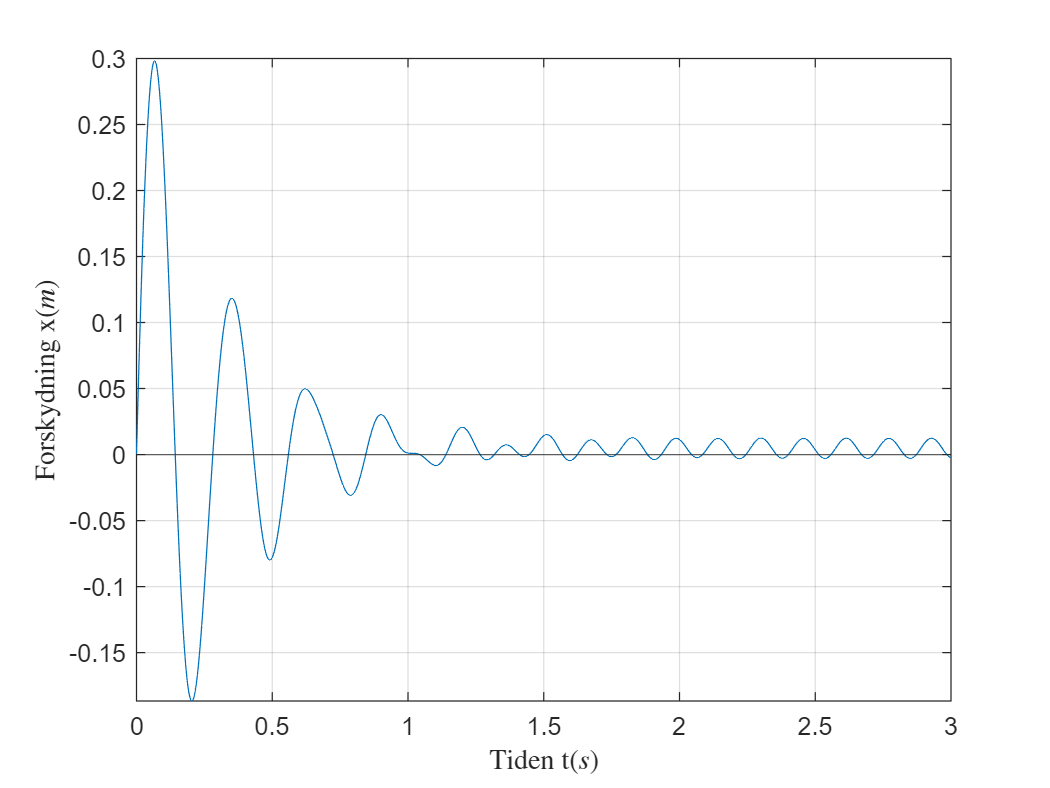

fplot(x(t), [t_0, 3]) %plot 
yline(0)
ylabel('Forskydning x($m$)', Interpreter='latex')
xlabel('Tiden t($s$)', Interpreter='latex')
grid()

Det ses på plottet at den complimentære del dør ud og til sidst har vi kun den drevne svigning